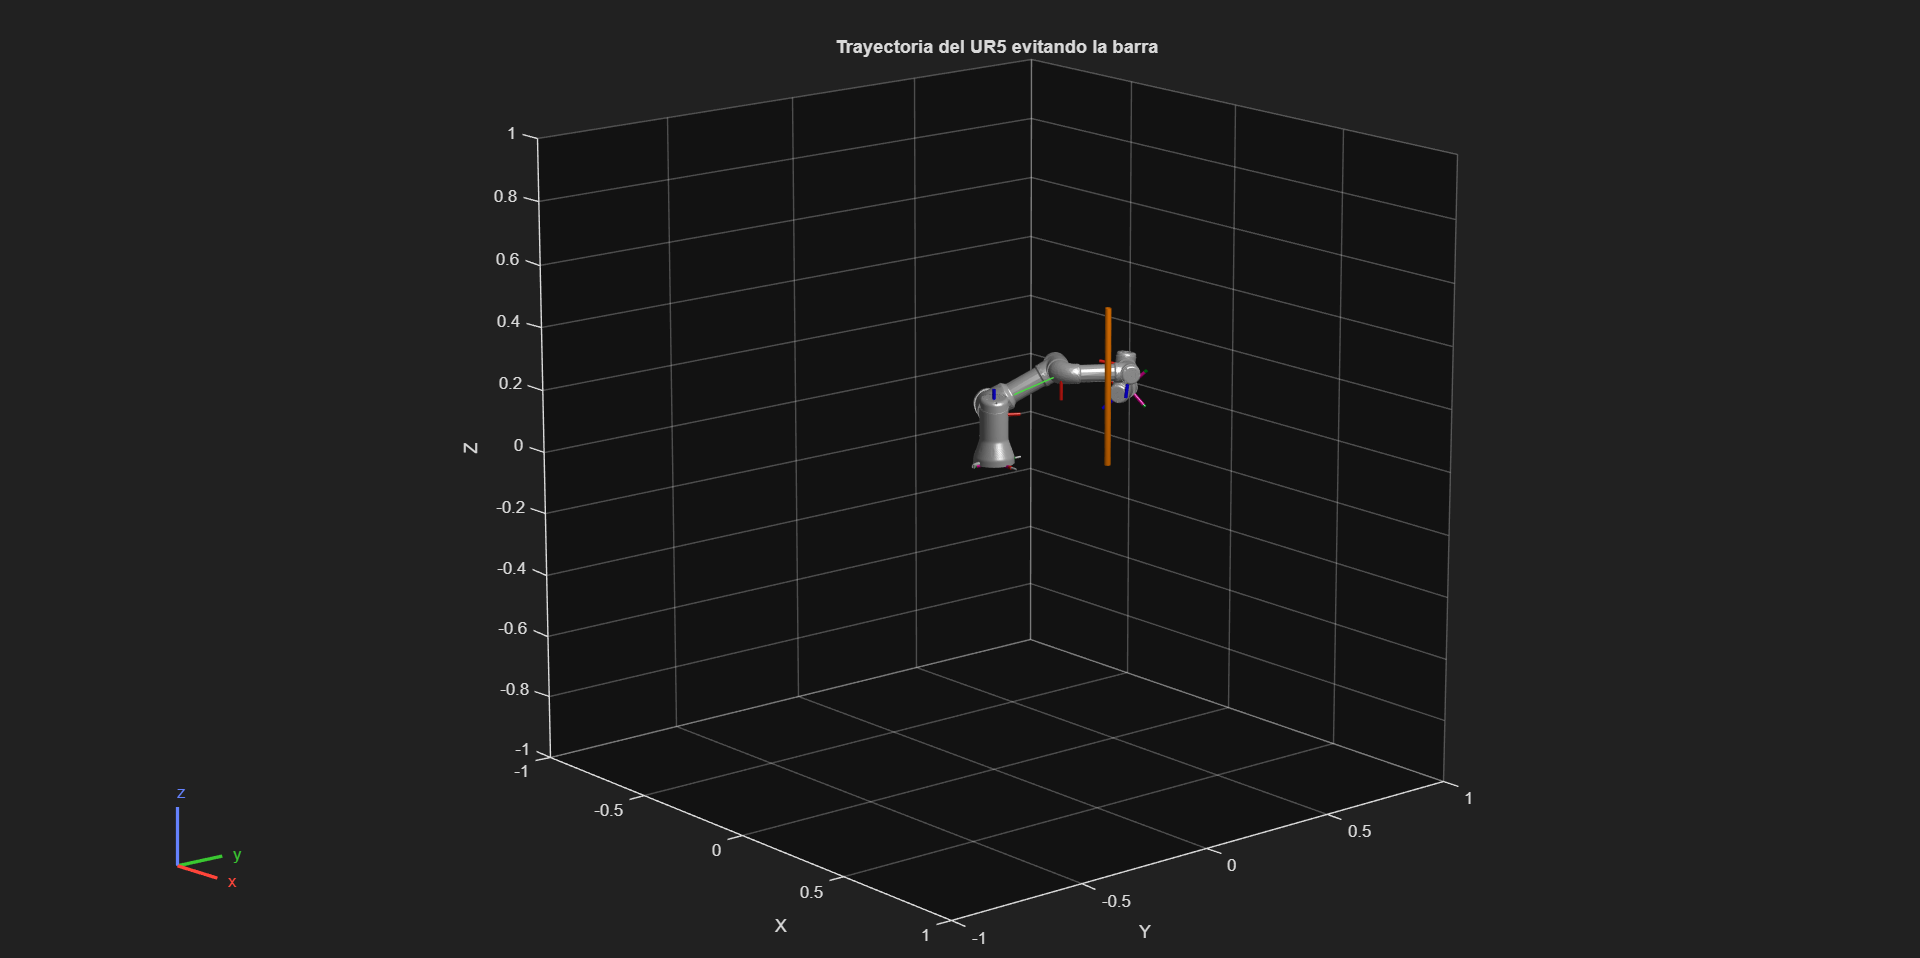

% Cargar el modelo del UR5
robot = loadrobot("universalUR3", "DataFormat", "row");

% Crear una barra como obstáculo (cilindro vertical)
radius = 0.01;      % Radio de la barra
height = 0.5;       % Altura de la barra
barra = collisionCylinder(radius, height);

% Posicionar la barra en el espacio (por ejemplo, al frente del robot)
barra.Pose = trvec2tform([0.25, 0.25, height/2]);  % centrada a z = altura/2

% Crear el planificador RRT
rrt = manipulatorRRT(robot, {barra});
rrt.SkippedSelfCollisions = "parent";
rrt.ValidationDistance = 0.1;

% Definir configuraciones válidas (UR5 tiene 6 DoF)
startConfig = [0.08 -0.65 0.05 0.02 0.04 0.49];

% Intentar encontrar una configuración de destino válida
%maxAttempts = 10;
%for i = 1:maxAttempts
    %goalConfig = randomConfiguration(robot);
    %if isConfigurationValid(rrt, goalConfig)
        %break;
    %end
%end
goalConfig = [1 -0.5 0.5 0.12 0.4 0.7];
% Planificar la trayectoria
rng(0);
path = plan(rrt, startConfig, goalConfig);

% Verificar que se obtuvo una trayectoria
if isempty(path)
    error('No se pudo encontrar una trayectoria que evite el obstáculo.');
end

% Interpolar y visualizar la trayectoria
interpPath = interpolate(rrt, path);

% Visualizar movimiento del robot evitando el obstáculo
figure;
for i = 1:size(interpPath,1)
    show(robot, interpPath(i,:), "PreservePlot", false);
    hold on;
    show(barra);
    title("Trayectoria del UR5 evitando la barra");
    view(50, 15);
    drawnow;
    pause(0.001);  % Aumenta el tiempo para que se vea el movimiento
end
hold off;